% Need to run LoadRawData.m
% Need to run preprocessData.mlx

numOfPulses = 0;
for i=1:size(pulseData_FunctionOutput, 2)
    numOfPulses = numOfPulses + (size(pulseData_FunctionOutput{i}, 2));
end

totalPulses = 1;
meanData = [numOfPulses, 12];
rmsData = [numOfPulses, 12];
shapeData = [numOfPulses, 12];
kurtosisData = [numOfPulses, 12];
skewnessData = [numOfPulses, 12];
for fileIndex = 1:size(pulseData_FunctionOutput, 2)
    for pulseIndex = 1:size(pulseData_FunctionOutput{fileIndex}, 2)
        for sensorIndex = 1:size(pulseData_FunctionOutput{fileIndex}{pulseIndex}, 2)
            pulse = pulseData_FunctionOutput{fileIndex}{pulseIndex}(:, sensorIndex);
            meanData(totalPulses, sensorIndex) = mean(pulse);
            rmsData(totalPulses, sensorIndex) = fnRMS(pulse);
            shapeData(totalPulses, sensorIndex) = fnShapeFactor(pulse);
            kurtosisData(totalPulses, sensorIndex) = fnKurtosis(pulse);
            skewnessData(totalPulses, sensorIndex) = fnSkewness(pulse);

        end
        totalPulses = totalPulses + 1;
    end
end

## Mean

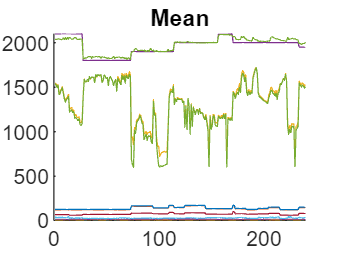

h1 = figure(1); hold on;
title("Mean");
for sensorIndex=1:size(meanData, 2)
    figure(1); hold on;
    plot(meanData(:, sensorIndex));
end

## RMS

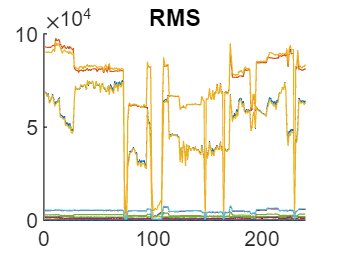

% RMS
h1 = figure(2); hold on;
title("RMS");
for sensorIndex=1:size(rmsData, 2)
    figure(2); hold on;
    plot(rmsData(:, sensorIndex));
end

## Shape Factor

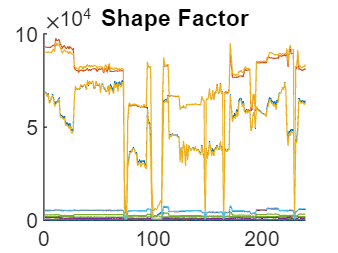

% Shape Factor
h1 = figure(2); hold on;
title("Shape Factor");
for sensorIndex=1:size(rmsData, 2)
    figure(2); hold on;
    plot(shapeData(:, sensorIndex));
end

## Kurtosis

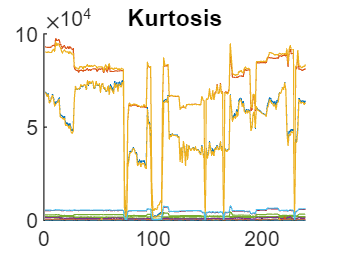

% quantifies the peak value of the PDF. 
% The kurtosis value for normal rolling element bearing is well-recognized as 3.
h1 = figure(3); hold on;
title("Kurtosis");
for sensorIndex=1:size(kurtosisData, 2)
    figure(2); hold on;
    plot(kurtosisData(:, sensorIndex));
end

## Skewness

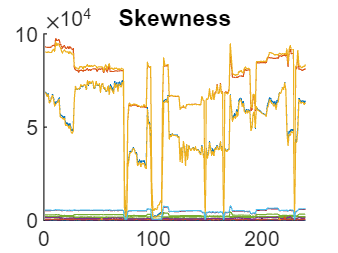

% Skewness quantifies the asymmetry behavior of vibration signal through its
% probability density function (PDF).
h2 = figure(4); hold on;
title("Skewness");
for sensorIndex=1:size(skewnessData, 2)
    figure(3); hold on;
    plot(skewnessData(:, sensorIndex));
end

## ccc